## Teoría de la Renovación

Nota del tema: La mayoría de los incisos o los problemas se solucionan corriendo uno o varias de las funciones anexas. Este texto está pensado en profundizar un poco más el tema visto en modelado II. Por ello se anexan múltiples gráficas y otros datos (inecesarios a simple vista) que podrían ser útiles para hacer análisis con mayor detalle, o bien si los problemas se vuelven interesantes. Se le recomienda al lector enfocarse en las respuestas puntuales a los incisos. 

### Problema 3

unidadTiempo = 1;%año
alpha = 4;%entradas al servicio por año
E_N = @(t) alpha*t

E_N = function_handle with value:
    @(t)alpha*t


ansA = E_N(5)%Numéro esperado de mantenimientos de cada camión en el periodo

ansA = 20

% de duración de la garantía t=5 años. 

ansB = ansA/4%El número esperado de mantenimientos pesados de cada camión en el periodo

ansB = 5

% de duración de la garantía 1 de cada cuatro

%ansC = P[W(4)<1]
ansC = ProcesoPosissonAcumulado(alpha, 4, 1)%Probabilidad de que el primer mantenimiento pesado se

ansC = 0.4335

%realice después del primer año de operación

%ansD = P(N(5)=20) La probabilidad de que se lleven a cabo 
%solamente 5 mantenimientos pesados en el periodo de garantía del camión.
ansD = ProcesoPosissonPuntual(alpha, 20, 5)

ansD = 0.0888


%ansE = E(W(9)) = n/alpha (formulazo)
andE = 9/alpha %años

andE = 2.2500

### Tarea 9: Exponencial vs Normal

Original t~N(60,12^2) a $400 el cartucho

Vertice t~exp(1/54) a $360 el cartucho

Nota importante y aclaratoria. Como podemos notar el proceso Poisson exige que el dato del tiempo sea 1 o bien un año. El proceso normal no puede obtener su resultado a partir de un 1 pues tiene su media en 60, pero ello necesita el dato en días. Podemos notar que la t fue almacenada como días y no años por ello al correr el proceso Poisson debemos dividir la t entre las unidades de tiempo, también al buscar los resultados esperados, dividimos entre las unidades de tiempo para obtener los resultados en años. 

promedio1 = 60;
miu = promedio1;
sigma = 12;
unidadTiempo = 240;%días en un año hábiles.

t = 1*unidadTiempo;%Queremos evaluar en un año o bien, una unidad de tiempo

%resA = P[N(1)=5]
resA = ProcesoNormal(t,5, miu, sigma)%La probabilidad de 

resA = 0.0127

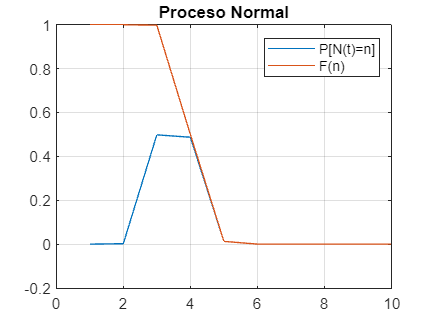

% tener 5 cambios de cartucho en una unidad de tiempo según un proceso normal


% Solo para que quede clara la evolución del proceso normal vamos a
% graficar. 
PNTn = ProcesoNormalGraficable(t,10, miu, sigma);


alpha1 = unidadTiempo/promedio1;
%resB = E(N(1))
resB = alpha1*t/unidadTiempo %Cantidad de entradas por año esperadas

resB = 4


promedio2 = 54;
lambda = 1/promedio2;
alpha2 = unidadTiempo/promedio2;
%resC = E(N(1))
resC = alpha2*t/unidadTiempo

resC = 4.4444


%resD = P[N(1)=5]
ansD = ProcesoPosissonPuntual(alpha2, 5, t/unidadTiempo)

ansD = 0.1697

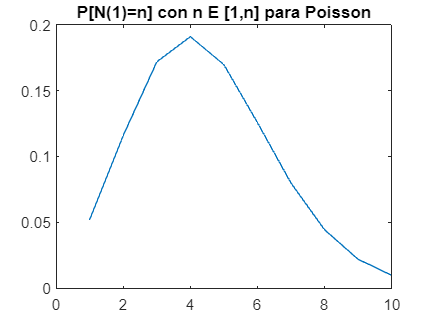

vecPoi =     0.0522    0.1160    0.1718    0.1909    0.1697    0.1257    0.0798    0.0443    0.0219    0.0097



% Solo para que quede clara la evolución del proceso poisson vamos a
% graficar. 
n = 10;
vecPoi = ProcesoPosissonGraficableVectorial(alpha2,n, t/unidadTiempo)


%Conclusión:
%AL multiplicar la cantidad esperada de reposiciones de cada método con su
%costo esperado llegamos al mismo resultado:
resB*400

ans = 1600

resC*360

ans = 1600

%De tal forma podría parecer que en primera instancia ninguna alternativa
%es mejor que la otra, sin emargo, 

for i=1:1:15
    vecNorm(i) = ProcesoNormal(t, i, miu, sigma);
    vecExp(i) = ProcesoPosissonPuntual(alpha2, i, t/unidadTiempo);
end
vecExp

vecExp =     0.0522    0.1160    0.1718    0.1909    0.1697    0.1257    0.0798    0.0443    0.0219    0.0097    0.0039    0.0015    0.0005    0.0002    0.0000


sum(vecNorm)*400

ans = 400.0001

sum(vecExp)*360

ans = 355.7660

%Al sumar todas las probabilidades en un panorama de tiempo grande  la
%multipliamos por el costo, obtenemos un valor esperado de la decisión. 

### Renovación Problema 8.

TMF~Norm(100,1600)

TAR~Norm(3, 1)

T = (TMF+TAR)~Norm(103,1601)

t = 360

a) probabilidad de no cobrar (1y2)

b) P[N(t)=3]

c) &Personal P(n=0)

miu1 = 100;
sigma1 = sqrt(1600);
miu2 = 3;
sigma2 = 1;
miu = miu1+miu2

miu = 103

sigma = sqrt(sigma1^2+sigma2^2)

sigma = 40.0125

t = 360 %días

t = 360

n = 10;
PNTn = ProcesoNormalAcumulado(t, n, miu, sigma)

PNTn =    -0.0018    0.2242    0.7419    0.9624    1.0007    1.0047    1.0050    1.0050    1.0050    1.0050


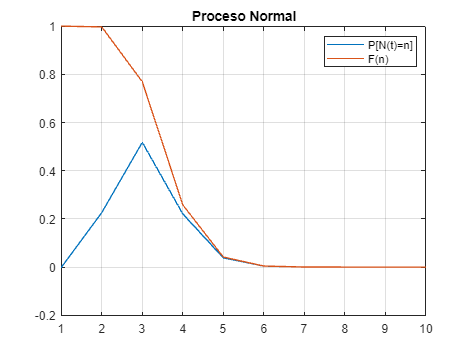

aux1 =    -0.0018    0.2260    0.5177    0.2205    0.0383    0.0040    0.0003    0.0000    0.0000    0.0000


aux1 = ProcesoNormalGraficable(t, n, miu, sigma)

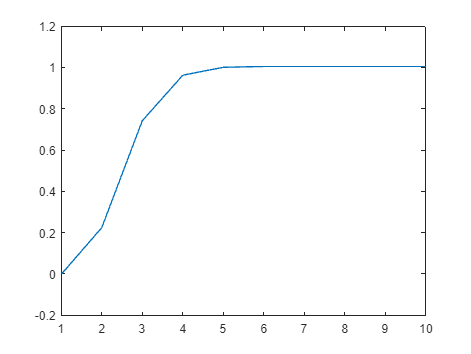

plot(PNTn)


%A) La probabilidad de no cobrar el seguro es la suma de los primeros 2
%elementos de el proceso normal graficable o símplemente el segundo
%elemento del acumulado.
resA = PNTn(2)

resA = 0.2242

resA_2= sum(aux1(1:2))

resA_2 = 0.2242



%B) Probabilidad de que sucedan 3 eventos en un periodo.
%Podemos utilizar el método de cálculo de proceso Poisson en un momento
%puntual o tomar el tecer elemento del graficable
nB = 3;
resB_1 = ProcesoNormal(t, nB, miu, sigma)

resB_1 = 0.5177

resB_2 = aux1(3)

resB_2 = 0.5177


%C), si notamos la gráfica del proceso normal graficable podemos ver que
%después del momento 6 la función acumulada F(t) empieza a ser cero y por
%lo tanto el proceso Normal también empieza a ser cero, por ello al tomar
%10 elementos podríamos afirmar que nos estamos moviendo al inifinito. 
%Para obtener la probabilidad del elemento cero que NO podríamos calcular
%utilizando directamente el proceso Normal (por errores en las integrales
%que no existen) simplemente debemos obtener el complemento de la
%probabilidad del intervalo.
Po = 1- PNTn(end-1)

Po = -0.0050

%Notamos que este valor es negativo, esto es imposible hablandod de
%probabilidades. Esto se debe a que el proceso Normal, como tal, NO existe
%y esto es una mera aproximación, para evitar probabilidades negativas
%dividimos entre el factor PT sin embargo, cuando se tratan de cosas TAN
%precisas es dificil mantener la cuenta, podemos afirmar que la Po en este
%caso es prácticamente 0. 

Procesos de renovación y series de fallas en el tiempo:

Podemos utilizar estar fórmula para calcular la probabilidad de que la falla número "n" suceda después del tiempo t.

Recordemos que 


$$\begin{array}{l}
N\left(t\right)\ge n\Leftrightarrow \textrm{Wn}\le t\\
N\left(t\right)<n\Leftrightarrow \textrm{Wn}>t\\
N\left(t\right)=n\Leftrightarrow \textrm{Wn}=t\\
N\left(t\right)\ge n+1\Leftrightarrow \textrm{Wn}+1\le t\\
N\left(t\right)<n+1\Leftrightarrow \textrm{Wn}+1>t
\end{array}$$


El proceso Poisson Acumulado calcula. Es decir, la probabilidad de que el accidente número n suceda después del tiempo t o bien que durante el tiempo t no haya sucedido el accidente número n.  Si quisieramos lo contrario siempre podemos obtener el complemente de esta probabilidad. 


$$N\left(t\right)<n\Leftrightarrow \textrm{Wn}>t$$


function [PWnt]  = ProcesoPosissonAcumulado(alpha, n, t)
    i = 0:n-1;
    PWnt = sum(exp(-alpha.*t)./(factorial(i)).*(alpha*t).^(i));
end

El proceso Poisson puntual calcula

La probabilidad de tener tantos accidentes (n) en el tiempo(t)


$$N\left(t\right)=n\Leftrightarrow \textrm{Wn}=t$$


function [PWnt]  = ProcesoPosissonPuntual(alpha, n, t)
    PWnt = (exp(-alpha.*t)./(factorial(n)).*(alpha*t).^(n));
end

Proceso Poissongraficable, calcula la probabilidad en múltiples puntos. 

function [y]  = ProcesoPosissonGraficableVectorial(alpha, n, t)
for i=1:1:n
    y(i) = ProcesoPosissonPuntual(alpha, i, t);
end
plot(y)
title("P[N(1)=n] con n E [1,n] para Poisson")
end

Función clásica del proceso normal que evalúa un solo punto. Notemos que las siguientes funciones son la cúspide de la infeficiencia pues hasta el final se me ocurrió que podríamos utilizar esta primera función y mandarla a llamar en las demás, salu2. 

function [PWnt]  = ProcesoNormal(t, n, miu, desStd)
    sigma = desStd;
    PT = normcdf(0,miu,sigma);
    Wnnow = normcdf(t,n*miu,sqrt(n)*sigma);
    Wnnow = Wnnow/(1-PT).^n;
    Wnsig = normcdf(t,(n+1)*miu,sqrt(n+1)*sigma);
    Wnsig = Wnsig/(1-PT).^(n+1);
    PWnt = Wnnow-Wnsig;
end

Con esta función pretendemos no regresar un valor puntual para una "n" del proceso Poisson sino TODAS en un invervalo que va desde 1 hasta n. Con ello pretendemos vizualizar el comportamiento de nuestro proceso. Esta función regresa un vector con los valores en los distintos puntos e imprime la gráfica del proceso contra la n y de la función de densidad acumulada de la normal. 

function [PWnt]  = ProcesoNormalGraficable(t, n, miu, desStd)
    PWnt = zeros(1,n);
    sigma = desStd;
    PT = normcdf(0,miu,sigma);
    for i=1:1:n
        Wnnow = normcdf(t,i*miu,sqrt(i)*sigma);
        Wnnow = Wnnow/(1-PT).^i;
        Wnsig = normcdf(t,(i+1)*miu,sqrt(i+1)*sigma);
        Wnsig = Wnsig/(1-PT).^(i+1);
        PWnt(i) = Wnnow-Wnsig;

        F(i) = normcdf(t,i*miu,sqrt(i)*sigma);
    end
    
    plot(PWnt)
    hold on
    plot(F)
    title("Proceso Normal")
    legend("P[N(t)=n]", "F(n)")
    grid on
    hold off
end

Con esta función podemos calcular los valores acumulados de un proceso Normal, esto es hacer

P(N(t)<=n)

function [PWnt]  = ProcesoNormalAcumulado(t, n, miu, desStd)
    PWnt = zeros(1,n);
    sigma = desStd;
    PT = normcdf(0,miu,sigma);
    PWnt(1) = normcdf(t,1*miu,sqrt(1)*sigma)/(1-PT).^1 - normcdf(t,(1+1)*miu,sqrt(1+1)*sigma)/(1-PT).^(1+1);
    for i=2:1:n
        Wnnow = normcdf(t,i*miu,sqrt(i)*sigma);
        Wnnow = Wnnow/(1-PT).^i;
        Wnsig = normcdf(t,(i+1)*miu,sqrt(i+1)*sigma);
        Wnsig = Wnsig/(1-PT).^(i+1);
        PWnt(i) = PWnt(i-1) + Wnnow-Wnsig;
    end
end
